% MATLAB Script for Meningioma FT-IR Classification: Outlier Detection
% Phase 1: Setup & Initial Data Exploration
% Sub-Step: Outlier Detection via PCA T2 Hotelling Square on Training Set

%clear; close all; clc;
disp('Starting Outlier Detection Script...');

Starting Outlier Detection Script...



%% --- 1. Setup: Paths, Parameters, and Colors ---
disp('1. Setup: Paths, parameters, and colors...');

1. Setup: Paths, parameters, and colors...



% Project Root Directory (PLEASE ADJUST IF NECESSARY)
projectBasePath = 'C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification'; % Your base path

% Directories
dataDir    = fullfile(projectBasePath, 'data');
resultsDir = fullfile(projectBasePath, 'results');
figuresDir = fullfile(projectBasePath, 'figures');

% Ensure results and figures directories exist
if ~isfolder(resultsDir); mkdir(resultsDir); end
if ~isfolder(figuresDir); mkdir(figuresDir); end

% Colors for visualization (as per Master Prompt)
colorWHO1 = [230, 153, 102] / 255; % Orange
colorWHO3 = [102, 179, 230] / 255; % Blue
colorOutlier = [255, 0, 0] / 255; % Red for outliers

% Parameters for outlier detection
alpha = 0.01; % Significance level for Hotelling T2 test
varianceToExplainForT2 = 0.95; % PCA variance for T2 calculation

% Filename prefix (current date)
% Current date is Wednesday, May 14, 2025
datePrefix = '20250514'; % Using provided date
% Alternatively, for dynamic date: datePrefix = string(datetime('now','Format','yyyyMMdd'));

disp('Setup completed.');

Setup completed.



%% --- 2. Load and Prepare Training Data from dataTableTrain ---
disp('2. Loading and Preparing Training Data from dataTableTrain...');

2. Loading and Preparing Training Data from dataTableTrain...



% This script assumes 'dataTableTrain' is already loaded into the MATLAB workspace.
% If not, you need to load it first. Example:
% disp("Attempting to load 'dataTableTrain' from a .mat file...");
% load(fullfile(dataDir, 'your_file_containing_dataTableTrain.mat'), 'dataTableTrain');
%
% Required columns in dataTableTrain: CombinedSpectra, WHO_Grade, Diss_ID
% CombinedSpectra{i} should contain an N x W matrix (Spectra x Wavenumbers)
% wavenumbers.mat (containing wavenumbers_roi) must be in dataDir.

try
    if ~exist('dataTableTrain', 'var')
        error(['dataTableTrain not found in workspace. Please load it before running this script. ' ...
               'Expected columns: CombinedSpectra, WHO_Grade, Diss_ID.']);
    end
    
    load(fullfile(dataDir, 'wavenumbers.mat'), 'wavenumbers_roi'); % Load wavenumbers
catch ME
    disp('Error during initial check for dataTableTrain or loading wavenumbers.mat.');
    disp('Ensure dataTableTrain is available in the workspace (with required columns),');
    disp('and wavenumbers.mat (with wavenumbers_roi) is in the dataDir.');
    rethrow(ME);
end

% Initialize cell arrays and vectors to store concatenated data
allSpectra_cell = {};
allLabels_cell = {};
allPatientIDs_cell = {};
allOriginalIndices_vec = []; % To store row index from dataTableTrain for each spectrum in X_train
allOriginalSpectrumIndices_Within_Sample_vec = []; % To store original index within each sample's CombinedSpectra

disp('Extracting spectra, labels, and patient IDs from dataTableTrain...');

Extracting spectra, labels, and patient IDs from dataTableTrain...


for i = 1:height(dataTableTrain)
    % Get the matrix of spectra for the current sample/patient
    % User confirmed: dataTableTrain.CombinedSpectra{i} is an [Number_of_Spectra x Number_of_Wavenumbers] matrix
    spectraMatrix_Raw = dataTableTrain.CombinedSpectra{i};
    
    if isempty(spectraMatrix_Raw)
        warning('Row %d of dataTableTrain: CombinedSpectra cell is empty. Skipping this row for X_train construction.', i);
        continue; % Skip if no spectra data for this entry
    end
    
    if ~isnumeric(spectraMatrix_Raw) || ndims(spectraMatrix_Raw) > 2 || isempty(spectraMatrix_Raw)
         warning('Row %d of dataTableTrain: CombinedSpectra does not contain a valid 2D numeric matrix or is empty after check. Skipping.', i);
        continue;
    end

    % Spectra are already rows (N x W). Assign directly.
    spectraForCurrentSample = spectraMatrix_Raw; 
    numIndividualSpectra = size(spectraForCurrentSample, 1);
    
    if numIndividualSpectra == 0
        warning('Row %d of dataTableTrain: CombinedSpectra cell yielded zero spectra. Skipping this row.', i);
        continue;
    end
    
    allSpectra_cell{end+1,1} = spectraForCurrentSample;
    
    currentLabel = dataTableTrain.WHO_Grade(i);
    allLabels_cell{end+1,1} = repmat(currentLabel, numIndividualSpectra, 1);
    
    currentPatientID_val = dataTableTrain.Diss_ID{i};
    if iscell(currentPatientID_val) && length(currentPatientID_val)==1
        currentPatientID_str = currentPatientID_val{1};
    elseif ischar(currentPatientID_val)
        currentPatientID_str = currentPatientID_val;
    else
        error('Row %d of dataTableTrain: Diss_ID has an unexpected format. Expected a string or a cell containing a single string.', i);
    end
    allPatientIDs_cell{end+1,1} = repmat({currentPatientID_str}, numIndividualSpectra, 1);

    allOriginalIndices_vec = [allOriginalIndices_vec; repmat(i, numIndividualSpectra, 1)];
    allOriginalSpectrumIndices_Within_Sample_vec = [allOriginalSpectrumIndices_Within_Sample_vec; (1:numIndividualSpectra)'];
end

if isempty(allSpectra_cell)
    error('No spectra could be extracted from dataTableTrain. Please check the CombinedSpectra column and its contents.');
end

X_train = cell2mat(allSpectra_cell);
y_train_categorical = cat(1, allLabels_cell{:});
Patient_ID_train = cat(1, allPatientIDs_cell{:});
Original_Indices_train = allOriginalIndices_vec; 
Original_Spectrum_Index_In_Sample_train = allOriginalSpectrumIndices_Within_Sample_vec;

% Convert y_train_categorical to numeric for PCA plot coloring and some model inputs
y_train_numeric = zeros(length(y_train_categorical), 1);
categories_y = categories(y_train_categorical);
who1_cat_str = 'WHO-1'; who3_cat_str = 'WHO-3';
idx_who1_in_cat = find(strcmp(categories_y, who1_cat_str));
idx_who3_in_cat = find(strcmp(categories_y, who3_cat_str));

if ~isempty(idx_who1_in_cat); y_train_numeric(y_train_categorical == categories_y{idx_who1_in_cat}) = 1; else warning('Category ''%s'' not found.', who1_cat_str); end
if ~isempty(idx_who3_in_cat); y_train_numeric(y_train_categorical == categories_y{idx_who3_in_cat}) = 3; else warning('Category ''%s'' not found.', who3_cat_str); end

if any(y_train_numeric == 0) && ~all(y_train_numeric == 0) % If some are mapped and some are not
    unmapped_mask = (y_train_numeric == 0);
    unmapped_cats = unique(y_train_categorical(unmapped_mask));
    warning('Some y_train labels were not mapped to numeric 1 or 3. Unmapped categories: %s.', strjoin(string(unmapped_cats),', '));
end
if all(y_train_numeric == 0) && ~isempty(y_train_categorical)
     error('No y_train labels were mapped to numeric 1 or 3. Check WHO_Grade values. Expected ''WHO-1'' and ''WHO-3''.');
end
y_train = y_train_categorical; % Keep y_train as categorical for functions that might need it

disp(['Training data extracted: ' num2str(size(X_train, 1)) ' total spectra (rows), ' num2str(size(X_train, 2)) ' wavenumbers (columns).']);

Training data extracted: 33792 total spectra (rows), 441 wavenumbers (columns).


disp(['Number of wavenumbers from wavenumbers_roi: ' num2str(length(wavenumbers_roi))]);

Number of wavenumbers from wavenumbers_roi: 441



if size(X_train, 2) ~= length(wavenumbers_roi)
    warning(['MISMATCH: Number of features in X_train (%d) vs. length of wavenumbers_roi (%d). Check data consistency!'], size(X_train,2), length(wavenumbers_roi));
end
disp('Data extraction and preparation completed.');

Data extraction and preparation completed.



%% --- 3. Perform PCA on Training Data ---
disp('3. Performing PCA on training data...');

3. Performing PCA on training data...


if isempty(X_train)
    error('X_train is empty. Cannot perform PCA. Check data extraction in Section 2.');
end
[coeff_train, score_train, latent_train, ~, explained_train, mu_train] = pca(X_train);

disp('PCA completed.');

PCA completed.


if ~isempty(explained_train)
    disp(['Variance explained by the first PC: ' num2str(explained_train(1), '%.2f') '%']);
    disp(['Variance explained by the first three PCs: ' num2str(sum(explained_train(1:min(3,length(explained_train)))), '%.2f') '%']);
else
    warning('PCA resulted in empty "explained_train". Check X_train content.');
end

Variance explained by the first PC: 50.17%


Variance explained by the first three PCs: 87.01%



cumulativeVariance = cumsum(explained_train);
numComponentsForT2 = find(cumulativeVariance >= varianceToExplainForT2*100, 1, 'first');
if isempty(numComponentsForT2)
    numComponentsForT2 = length(explained_train); 
end
if numComponentsForT2 == 0 && ~isempty(explained_train) % Handle case where no component meets threshold, use at least 1 if possible
    numComponentsForT2 = 1;
end
if isempty(explained_train) || numComponentsForT2 == 0 % If still zero (e.g. X_train was constant)
    error('Could not determine a valid number of components for T2 calculation. Check PCA results and X_train.');
end
disp(['Number of PCs for T2 calculation (explaining >= ' num2str(varianceToExplainForT2*100) '% variance): ' num2str(numComponentsForT2)]);

Number of PCs for T2 calculation (explaining >= 95% variance): 6



%% --- 4. Calculate Hotelling's T-Squared Statistic ---
disp('4. Calculating Hotelling T-Squared statistic...');

4. Calculating Hotelling T-Squared statistic...


score_t2 = score_train(:, 1:numComponentsForT2);
latent_t2 = latent_train(1:numComponentsForT2);
if any(latent_t2 <= 0)
    warning('Some selected latent roots (variances) for T2 are zero or negative. Clamping to a small positive value.');
    latent_t2(latent_t2 <= 0) = eps; % Prevent division by zero
end
T2_values = sum(bsxfun(@rdivide, score_t2.^2, latent_t2'), 2);
disp('Hotelling T-Squared values calculated.');

Hotelling T-Squared values calculated.



%% --- 5. Determine Outlier Threshold ---
disp('5. Determining outlier threshold...');

5. Determining outlier threshold...


n_samples = size(X_train, 1);
% Using F-distribution based threshold (more robust for smaller n_samples)
if n_samples > numComponentsForT2 && numComponentsForT2 > 0
    T2_threshold = ((numComponentsForT2 * (n_samples - 1)) / (n_samples - numComponentsForT2)) * finv(1 - alpha, numComponentsForT2, n_samples - numComponentsForT2);
    disp(['Hotelling T2 threshold (F-distribution, alpha=' num2str(alpha) ', df1=' num2str(numComponentsForT2) ', df2=' num2str(n_samples - numComponentsForT2) '): ' num2str(T2_threshold)]);
else
    disp('Warning: Cannot use F-distribution threshold (n_samples <= numComponentsForT2 or numComponentsForT2=0). Falling back to Chi-squared.');
    T2_threshold = chi2inv(1 - alpha, numComponentsForT2);
    disp(['Hotelling T2 threshold (Chi-squared, alpha=' num2str(alpha) ', df=' num2str(numComponentsForT2) '): ' num2str(T2_threshold)]);
end

Hotelling T2 threshold (F-distribution, alpha=0.01, df1=6, df2=33786): 16.8176


if isnan(T2_threshold) || isinf(T2_threshold)
    error('Calculated T2_threshold is NaN or Inf. Check parameters and input data for T2 calculation.');
end

%% --- 6. Identify Outliers ---
disp('6. Identifying outliers...');

6. Identifying outliers...


outlier_indices_logical = T2_values > T2_threshold;
outlier_indices_numeric = find(outlier_indices_logical);
num_outliers = sum(outlier_indices_logical);
disp([num2str(num_outliers) ' outliers identified in the training set (X_train).']);

2418 outliers identified in the training set (X_train).



if num_outliers > 0
    disp('Global indices of identified outliers (relative to X_train):');
    disp(outlier_indices_numeric');
    Patient_ID_outliers = Patient_ID_train(outlier_indices_logical);
    disp('Patient IDs of identified outliers:');
    disp(unique(Patient_ID_outliers)'); 
    Original_Indices_DataTable_Row_Outliers = Original_Indices_train(outlier_indices_logical);
    disp('Original row indices in dataTableTrain for these outliers:');
    disp(unique(Original_Indices_DataTable_Row_Outliers)');
else
    disp('No outliers identified in X_train according to the chosen threshold.');
end

Global indices of identified outliers (relative to X_train):


          10          15          16          26          32          48         120         130         147         164         215         274         275         290         340         359         368         375         390         394         395         396         397         398         399         400         406         422         438         542         677         715         716         734         735         800        1092        1288        1442        2336        3160        3218        3234        3250        3279        3282        3296        3298        3595        3607        3630        3649        3650        3651        3659        3662        3665        3666        3673        3675        3677        3693        3712        3764        3774        3780        3816        3831        3832        3833        3841        3842        3843        3844        3845        3846        3847        3848        3849        3850        3851        3852        3853    

Patient IDs of identified outliers:


    {'MEN-002-01'}    {'MEN-003-01'}    {'MEN-005-01'}    {'MEN-010-01'}    {'MEN-011-01'}    {'MEN-019-01'}    {'MEN-020-01'}    {'MEN-033-01'}    {'MEN-037-01'}    {'MEN-044-02'}    {'MEN-050-01'}    {'MEN-080-01'}    {'MEN-081-02'}    {'MEN-083-01'}    {'MEN-087-01'}    {'MEN-093-01'}    {'MEN-097-01'}    {'MEN-098-01'}    {'MEN-099-01'}    {'MEN-101-01'}



Original row indices in dataTableTrain for these outliers:


     1     2     4     5     6    10    11    16    19    22    23    24    27    29    33    35    40    41    42    44




%% --- 7. Visualize Results ---
disp('7. Visualizing results...');

7. Visualizing results...


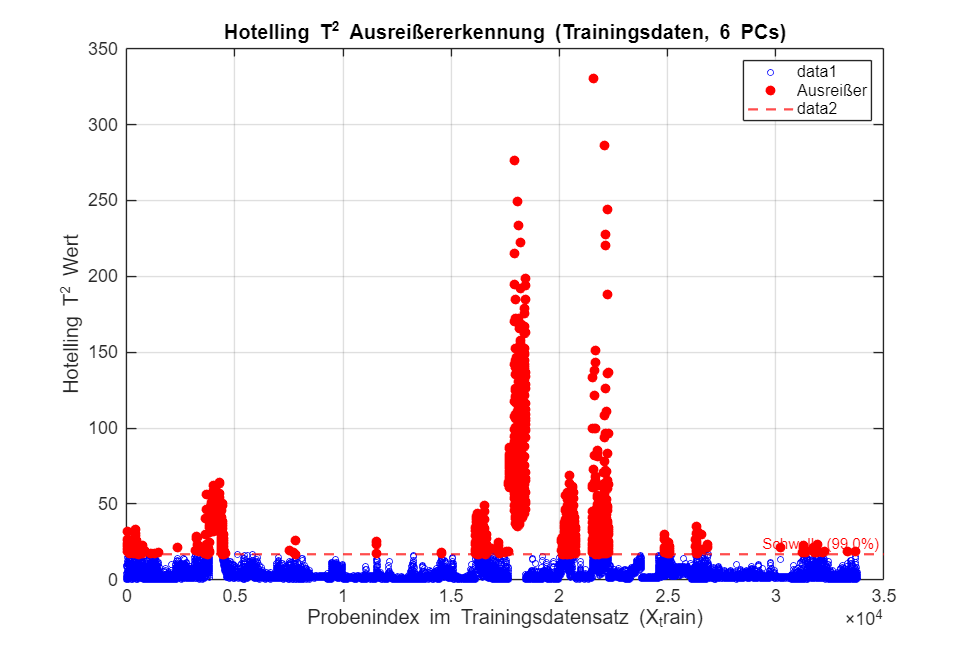

% Plot 1: Hotelling's T-Squared Values
% ... (this part was fine) ...
figT2 = figure('Name', 'Hotelling T2 Outlier Detection', 'Position', [100, 100, 900, 600]);
plot(1:length(T2_values), T2_values, 'ob', 'MarkerSize', 4); hold on;
if num_outliers > 0
    plot(outlier_indices_numeric, T2_values(outlier_indices_logical), 'o', 'Color', colorOutlier, 'MarkerFaceColor', colorOutlier, 'MarkerSize', 6, 'DisplayName', 'Ausreißer');
end
yline(T2_threshold, '--r', ['Schwelle (' num2str((1-alpha)*100, '%.1f') '%)'], 'LineWidth', 1.5);
hold off; xlabel('Probenindex im Trainingsdatensatz (X_train)'); ylabel('Hotelling T^2 Wert');
title(['Hotelling T^2 Ausreißererkennung (Trainingsdaten, ' num2str(numComponentsForT2) ' PCs)'], 'FontSize', 14);
legend('show', 'Location', 'northeast'); grid on; set(gca, 'FontSize', 12);

figName_T2_tiff = strcat(datePrefix, '_PCA_HotellingT2_Plot.tiff');
exportgraphics(figT2, fullfile(figuresDir, figName_T2_tiff), 'Resolution', 300);

figName_T2_fig = strcat(datePrefix, '_PCA_HotellingT2_Plot.fig');
savefig(figT2, fullfile(figuresDir, figName_T2_fig));
disp(['T2 plot saved as: ' fullfile(figuresDir, figName_T2_tiff)]);

T2 plot saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_HotellingT2_Plot.tiff


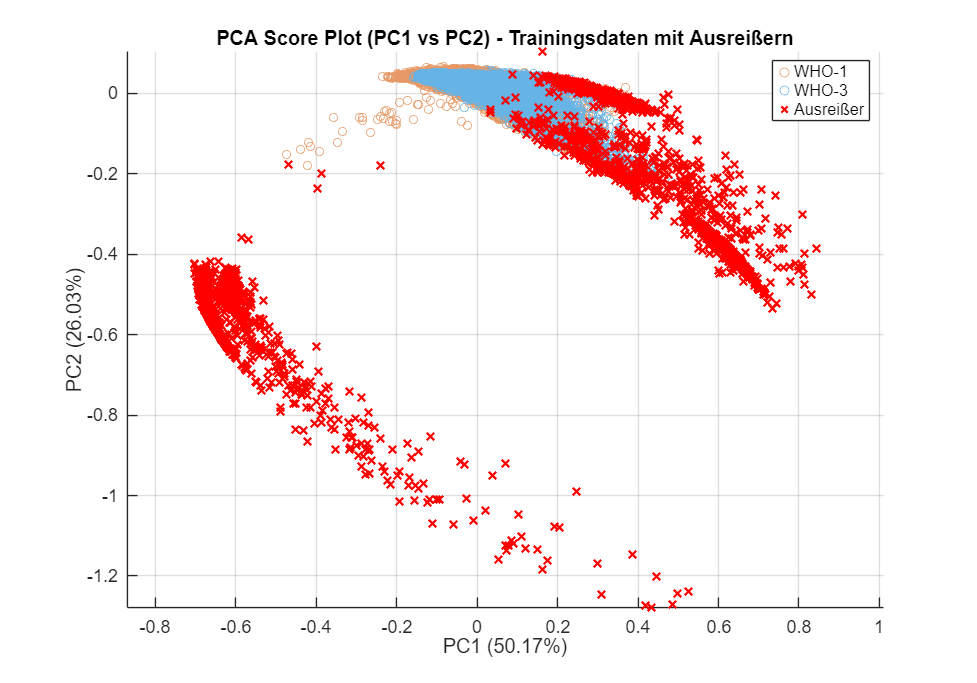


% Plot 2: PCA Score Plot (PC1 vs PC2)
figPCA = figure('Name', 'PCA Score Plot mit Ausreißern', 'Position', [150, 150, 1000, 700]);
hold on;
numPCsToPlotTotal = size(score_train,2); % Total available PCs from PCA
pc_for_x_axis = 1;

% --- CORRECTED LOGIC FOR pc_for_y_axis ---
if numPCsToPlotTotal >= 2
    pc_for_y_axis = 2;
else
    pc_for_y_axis = 1; % If only 1 PC available, use PC1 for both axes for consistency in scatter call
end
% --- END OF CORRECTION ---

isWHO1_non_outlier = (y_train_numeric == 1) & ~outlier_indices_logical;
if any(isWHO1_non_outlier) && pc_for_x_axis <= numPCsToPlotTotal && pc_for_y_axis <= numPCsToPlotTotal
    scatter(score_train(isWHO1_non_outlier, pc_for_x_axis), score_train(isWHO1_non_outlier, pc_for_y_axis), 30, colorWHO1, 'o', 'DisplayName', 'WHO-1');
end
isWHO3_non_outlier = (y_train_numeric == 3) & ~outlier_indices_logical;
if any(isWHO3_non_outlier) && pc_for_x_axis <= numPCsToPlotTotal && pc_for_y_axis <= numPCsToPlotTotal
    scatter(score_train(isWHO3_non_outlier, pc_for_x_axis), score_train(isWHO3_non_outlier, pc_for_y_axis), 30, colorWHO3, 'o', 'DisplayName', 'WHO-3');
end
if num_outliers > 0 && pc_for_x_axis <= numPCsToPlotTotal && pc_for_y_axis <= numPCsToPlotTotal
    scatter(score_train(outlier_indices_logical, pc_for_x_axis), score_train(outlier_indices_logical, pc_for_y_axis), ...
            50, colorOutlier, 'x', 'LineWidth', 1.5, 'DisplayName', 'Ausreißer');
end
hold off; 

% Ensure explained_train is not empty and indices are valid
if ~isempty(explained_train) && pc_for_x_axis <= length(explained_train)
    xlabel_str = ['PC' num2str(pc_for_x_axis) ' (' num2str(explained_train(pc_for_x_axis), '%.2f') '%)'];
else
    xlabel_str = ['PC' num2str(pc_for_x_axis)];
end
xlabel(xlabel_str);

if pc_for_y_axis ~= pc_for_x_axis && ~isempty(explained_train) && pc_for_y_axis <= length(explained_train)
    ylabel_str = ['PC' num2str(pc_for_y_axis) ' (' num2str(explained_train(pc_for_y_axis), '%.2f') '%)'];
elseif pc_for_y_axis == pc_for_x_axis && numPCsToPlotTotal < 2
     ylabel_str = ['(Only PC' num2str(pc_for_x_axis) ' available)'];
else
    ylabel_str = ['PC' num2str(pc_for_y_axis)];
end
ylabel(ylabel_str);

title_str = 'PCA Score Plot - Trainingsdaten mit Ausreißern';
if pc_for_y_axis ~= pc_for_x_axis
    title_str = strrep(title_str, 'Plot', ['Plot (PC' num2str(pc_for_x_axis) ' vs PC' num2str(pc_for_y_axis) ')']);
end
title(title_str, 'FontSize', 14);
legend('show', 'Location', 'best'); grid on; axis equal; set(gca, 'FontSize', 12);

figName_PCA_tiff = strcat(datePrefix, '_PCA_ScorePlot_Outliers.tiff');
exportgraphics(figPCA, fullfile(figuresDir, figName_PCA_tiff), 'Resolution', 300);

figName_PCA_fig = strcat(datePrefix, '_PCA_ScorePlot_Outliers.fig');
savefig(figPCA, fullfile(figuresDir, figName_PCA_fig));
disp(['PCA score plot saved as: ' fullfile(figuresDir, figName_PCA_tiff)]);

PCA score plot saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_ScorePlot_Outliers.tiff


disp('Visualization completed.');

Visualization completed.



%% --- 8. Save Outlier Information (Global X_train context) ---
disp('8. Saving global outlier information (relative to X_train)...');

8. Saving global outlier information (relative to X_train)...


outlierInfo = struct();
outlierInfo.scriptRunDate = string(datetime(datePrefix,'InputFormat','yyyyMMdd','Format','yyyy-MM-dd'));
outlierInfo.alpha = alpha;
outlierInfo.varianceToExplainForT2 = varianceToExplainForT2;
outlierInfo.numComponentsForT2 = numComponentsForT2;
outlierInfo.T2_threshold = T2_threshold;
outlierInfo.outlier_global_indices_in_X_train = outlier_indices_numeric;
if num_outliers > 0
    outlierInfo.outlier_Original_Indices_dataTableTrain_Row = Original_Indices_train(outlier_indices_logical);
    outlierInfo.outlier_Original_Spectrum_Index_In_Sample = Original_Spectrum_Index_In_Sample_train(outlier_indices_logical);
    outlierInfo.Patient_ID_outliers = Patient_ID_train(outlier_indices_logical);
    outlierInfo.T2_values_of_outliers = T2_values(outlier_indices_logical);
else
    outlierInfo.outlier_Original_Indices_dataTableTrain_Row = [];
    outlierInfo.outlier_Original_Spectrum_Index_In_Sample = [];
    outlierInfo.Patient_ID_outliers = {};
    outlierInfo.T2_values_of_outliers = [];
end
outlierInfo.analysisDate = string(datetime('now','Format','yyyy-MM-dd HH:mm:ss'));

resultsFilename_mat = strcat(datePrefix, '_PCA_HotellingT2_GlobalOutlierInfo.mat');
save(fullfile(resultsDir, resultsFilename_mat), 'outlierInfo');
disp(['Global outlier information saved in: ' fullfile(resultsDir, resultsFilename_mat)]);

Global outlier information saved in: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_PCA_HotellingT2_GlobalOutlierInfo.mat



if num_outliers > 0 && exist('dataTableTrain','var') % Only create table if outliers and dataTableTrain exist
    T_global_outliers = table(Patient_ID_train(outlier_indices_logical), ...
                       outlier_indices_numeric, ... % Index in X_train
                       Original_Indices_train(outlier_indices_logical), ... % Row in dataTableTrain
                       Original_Spectrum_Index_In_Sample_train(outlier_indices_logical), ... % Index within that sample's original spectra
                       T2_values(outlier_indices_logical), ...
                       'VariableNames', {'Patient_ID', 'GlobalIndex_in_X_train', 'Orig_Row_dataTableTrain', 'Orig_Index_In_Sample', 'T2_Value'});
    resultsFilename_csv = strcat(datePrefix, '_PCA_HotellingT2_GlobalOutlierList.csv');
    writetable(T_global_outliers, fullfile(resultsDir, resultsFilename_csv));
    disp(['Global outlier list saved in: ' fullfile(resultsDir, resultsFilename_csv)]);
end

Global outlier list saved in: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_PCA_HotellingT2_GlobalOutlierList.csv


disp('Saving global outlier information completed.');

Saving global outlier information completed.



%% --- 9. Create Cleaned Flat Dataset for Machine Learning ---
disp('9. Creating cleaned flat dataset (X_train_no_outliers, etc.) for ML...');

9. Creating cleaned flat dataset (X_train_no_outliers, etc.) for ML...


good_indices_logical = ~outlier_indices_logical;

X_train_no_outliers = X_train(good_indices_logical, :);
y_train_no_outliers = y_train(good_indices_logical, :); 
Patient_ID_train_no_outliers = Patient_ID_train(good_indices_logical);
Original_Indices_train_no_outliers = Original_Indices_train(good_indices_logical);
Original_Spectrum_Index_In_Sample_train_no_outliers = Original_Spectrum_Index_In_Sample_train(good_indices_logical);
y_train_numeric_no_outliers = y_train_numeric(good_indices_logical);


disp([num2str(num_outliers) ' outliers removed from X_train.']);

2418 outliers removed from X_train.


disp(['Size of cleaned X_train_no_outliers: ' ...
      num2str(size(X_train_no_outliers, 1)) ' samples x ' ...
      num2str(size(X_train_no_outliers, 2)) ' features.']);

Size of cleaned X_train_no_outliers: 31374 samples x 441 features.



cleanedTrainingSetFilename = fullfile(dataDir, 'training_set_no_outliers.mat');
save(cleanedTrainingSetFilename, ...
     'X_train_no_outliers', 'y_train_no_outliers', 'y_train_numeric_no_outliers', ...
     'Patient_ID_train_no_outliers', ...
     'Original_Indices_train_no_outliers', ...
     'Original_Spectrum_Index_In_Sample_train_no_outliers', ...
     'wavenumbers_roi', 'mu_train', 'coeff_train'); % Save PCA model parameters from training too
disp(['Cleaned flat training dataset for ML saved in: ' cleanedTrainingSetFilename]);

Cleaned flat training dataset for ML saved in: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\data\training_set_no_outliers.mat


disp('--- Creation of cleaned flat dataset for ML completed. ---');

--- Creation of cleaned flat dataset for ML completed. ---



%% --- 10. Create New Table with Cleaned Spectra and Outlier Information per Sample ---
disp('10. Creating new table with cleaned spectra and outlier details per sample from dataTableTrain...');

10. Creating new table with cleaned spectra and outlier details per sample from dataTableTrain...



if ~exist('dataTableTrain', 'var')
    warning('dataTableTrain does not exist. Skipping creation of detailed cleaned table.');
else
    dataTableTrain_cleaned = dataTableTrain; 
    numSamplesInTable = height(dataTableTrain_cleaned);
    dataTableTrain_cleaned.OutlierSpectra = cell(numSamplesInTable, 1);
    dataTableTrain_cleaned.OutlierIndicesInSample = cell(numSamplesInTable, 1);

    if ~isempty(X_train)
        numWavenumbers = size(X_train, 2);
    elseif exist('wavenumbers_roi', 'var') && ~isempty(wavenumbers_roi)
        numWavenumbers = length(wavenumbers_roi);
    else
        error('Cannot determine the number of wavenumbers for empty outlier matrices in Section 10.');
    end

    for i = 1:numSamplesInTable
        originalSampleSpectra_N_x_W = dataTableTrain.CombinedSpectra{i};
        
        if isempty(originalSampleSpectra_N_x_W) || ~isnumeric(originalSampleSpectra_N_x_W) || ndims(originalSampleSpectra_N_x_W) > 2
            dataTableTrain_cleaned.CombinedSpectra{i} = zeros(0, numWavenumbers);
            dataTableTrain_cleaned.OutlierSpectra{i} = zeros(0, numWavenumbers);
            dataTableTrain_cleaned.OutlierIndicesInSample{i} = [];
            continue;
        end
        
        global_indices_for_current_sample = find(Original_Indices_train == i);
        
        if isempty(global_indices_for_current_sample)
            dataTableTrain_cleaned.OutlierSpectra{i} = zeros(0, numWavenumbers);
            dataTableTrain_cleaned.OutlierIndicesInSample{i} = [];
            % CombinedSpectra{i} in dataTableTrain_cleaned remains as original (no outliers from this sample were in X_train)
            continue;
        end
        
        outlier_status_for_these_spectra = outlier_indices_logical(global_indices_for_current_sample);
        original_internal_indices_for_these_spectra = Original_Spectrum_Index_In_Sample_train(global_indices_for_current_sample);
        
        internal_indices_of_outliers = original_internal_indices_for_these_spectra(outlier_status_for_these_spectra);
        internal_indices_of_outliers = sort(unique(internal_indices_of_outliers));
        
        internal_indices_of_good_spectra = original_internal_indices_for_these_spectra(~outlier_status_for_these_spectra);
        internal_indices_of_good_spectra = sort(unique(internal_indices_of_good_spectra));

        dataTableTrain_cleaned.OutlierIndicesInSample{i} = internal_indices_of_outliers;
        
        if ~isempty(internal_indices_of_outliers)
            dataTableTrain_cleaned.OutlierSpectra{i} = originalSampleSpectra_N_x_W(internal_indices_of_outliers, :);
        else
            dataTableTrain_cleaned.OutlierSpectra{i} = zeros(0, size(originalSampleSpectra_N_x_W, 2)); % Use actual numWavenumbers from sample
        end
        
        if ~isempty(internal_indices_of_good_spectra)
            dataTableTrain_cleaned.CombinedSpectra{i} = originalSampleSpectra_N_x_W(internal_indices_of_good_spectra, :);
        else
            dataTableTrain_cleaned.CombinedSpectra{i} = zeros(0, size(originalSampleSpectra_N_x_W, 2));
        end
    end

    newTableFilename_mat = strcat(datePrefix, '_dataTableTrain_CleanedAndOutliers.mat');
    save(fullfile(resultsDir, newTableFilename_mat), 'dataTableTrain_cleaned');
    disp(['New table with per-sample cleaned spectra and outlier details saved as: ' fullfile(resultsDir, newTableFilename_mat)]);

    % Excel overview
    newTableFilename_xlsx = strcat(datePrefix, '_dataTableTrain_CleanedAndOutliers_Overview.xlsx');
    try
        dataTableTrain_cleaned_for_excel = dataTableTrain_cleaned;
        dataTableTrain_cleaned_for_excel.NumOriginalSpectra = cellfun(@(x) size(x,1), dataTableTrain.CombinedSpectra);
        dataTableTrain_cleaned_for_excel.NumCleanedSpectra = cellfun(@(x) size(x,1), dataTableTrain_cleaned.CombinedSpectra);
        dataTableTrain_cleaned_for_excel.NumOutlierSpectra = cellfun(@(x) size(x,1), dataTableTrain_cleaned.OutlierSpectra);
        dataTableTrain_cleaned_for_excel.OutlierIndicesInSample_str = cellfun(@(x) num2str(x(:)'), dataTableTrain_cleaned.OutlierIndicesInSample, 'UniformOutput', false); % Ensure row vector string

        defaultColsToRemoveForExcel = {'CombinedSpectra', 'OutlierSpectra', 'PositionSpectra', 'CombinedRawSpectra', 'MeanSpectrum', 'OutlierIndicesInSample'};
        colsInTable = dataTableTrain_cleaned_for_excel.Properties.VariableNames;
        colsToRemoveForExcel = intersect(defaultColsToRemoveForExcel, colsInTable);
        
        varsToExport = setdiff(colsInTable, colsToRemoveForExcel, 'stable');
        newSummaryCols = {'NumOriginalSpectra', 'NumCleanedSpectra', 'NumOutlierSpectra', 'OutlierIndicesInSample_str'};
        newSummaryCols = newSummaryCols(ismember(newSummaryCols, colsInTable)); % Ensure these new summary columns actually exist
        varsToExport = [varsToExport, newSummaryCols];
        varsToExport = unique(varsToExport, 'stable'); % Remove duplicates if any

        writetable(dataTableTrain_cleaned_for_excel(:, varsToExport), fullfile(resultsDir, newTableFilename_xlsx));
        disp(['Overview of the new table (metadata only) saved as: ' fullfile(resultsDir, newTableFilename_xlsx)]);
    catch ME_excel
        disp(['Could not save Excel overview of detailed table: ' ME_excel.message]);
    end
    disp('--- Creation of detailed cleaned table completed. ---');
end

New table with per-sample cleaned spectra and outlier details saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_dataTableTrain_CleanedAndOutliers.mat


Overview of the new table (metadata only) saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_dataTableTrain_CleanedAndOutliers_Overview.xlsx


--- Creation of detailed cleaned table completed. ---



disp('Outlier Detection Script Finished.');

Outlier Detection Script Finished.


disp('Erstelle Plots: Mittelwert Nicht-Ausreißer (Schwarz) vs. Alle Ausreißer (Rot, transparent)...');

Erstelle Plots: Mittelwert Nicht-Ausreißer (Schwarz) vs. Alle Ausreißer (Rot, transparent)...


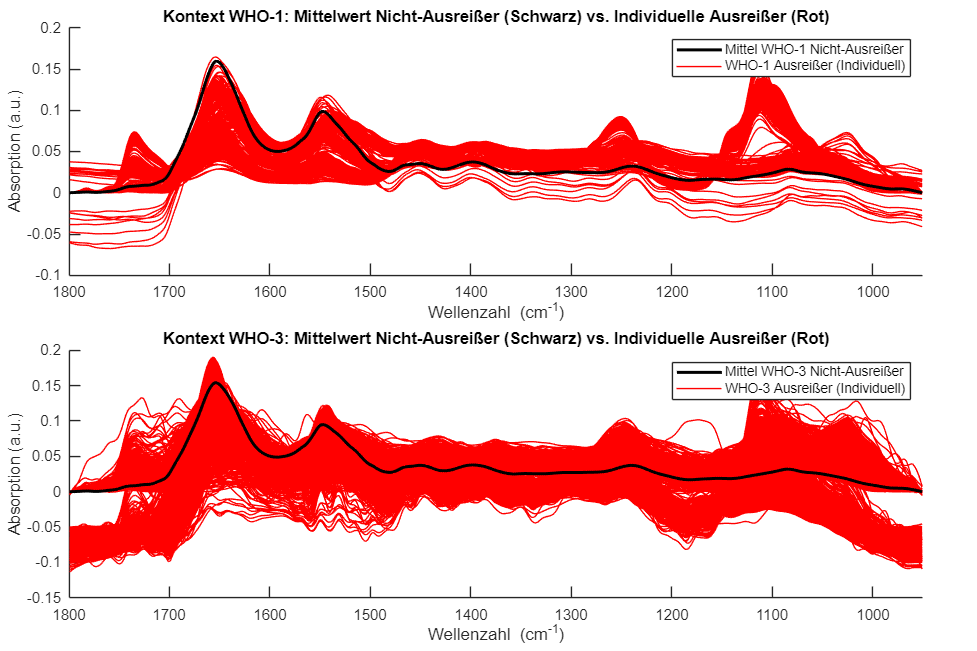


% --- Datenaufbereitung (wie zuvor) ---
non_outlier_indices_logical = ~outlier_indices_logical;
isWHO1 = (y_train_categorical == 'WHO-1');
isWHO3 = (y_train_categorical == 'WHO-3');

spectraWHO1_non_outliers = X_train(non_outlier_indices_logical & isWHO1, :);
spectraWHO3_non_outliers = X_train(non_outlier_indices_logical & isWHO3, :);

spectraWHO1_outliers = X_train(outlier_indices_logical & isWHO1, :);
spectraWHO3_outliers = X_train(outlier_indices_logical & isWHO3, :);

meanSpectrumWHO1_non_outlier = mean(spectraWHO1_non_outliers, 1);
meanSpectrumWHO3_non_outlier = mean(spectraWHO3_non_outliers, 1);

% --- Plot erstellen ---
figCompareBlackMeanToRedOutliers = figure('Name', 'Vergleich: Mittelwert Nicht-Ausreißer (Schwarz) vs. Ausreißer (Rot)', 'Position', [200, 200, 1200, 800]);
tiledlayout(2,1, 'TileSpacing', 'compact', 'Padding', 'compact');

% Annahme: colorOutlier ist bereits definiert
% colorOutlier = [1 0 0]; % Reines Rot (oder [255 0 0]/255)
black_color_mean = [0 0 0]; % Schwarz

alpha_value_individual_outliers = 0.3; % Transparenzwert für einzelne rote Ausreißer
linewidth_individual_outliers = 0.5;
linewidth_mean_non_outlier_black = 2.0; % Dicke für die schwarze Mittelwertslinie

% --- Plot für WHO-1 Kontext ---
nexttile;
hold on;

% 1. Alle einzelnen WHO-1 Ausreißer-Spektren plotten (semi-transparent rot, dünn)
legend_handle_outlier_who1 = [];
if ~isempty(spectraWHO1_outliers)
    for k = 1:size(spectraWHO1_outliers, 1)
        plot(wavenumbers_roi, spectraWHO1_outliers(k,:), ...
             'Color', [colorOutlier, alpha_value_individual_outliers], ...
             'LineWidth', linewidth_individual_outliers, ...
             'HandleVisibility','off'); 
    end
    if size(spectraWHO1_outliers, 1) > 0
        % Einen Plot für die Legende der Ausreißer
        legend_handle_outlier_who1 = plot(wavenumbers_roi, spectraWHO1_outliers(1,:), ... 
             'Color', [colorOutlier, alpha_value_individual_outliers], ...
             'LineWidth', linewidth_individual_outliers, ...
             'DisplayName', 'WHO-1 Ausreißer (Individuell)');
    end
end

% 2. Mittelwertspektrum der WHO-1 Nicht-Ausreißer plotten (dick, schwarz, im Vordergrund)
legend_handle_mean_who1 = [];
if ~isempty(meanSpectrumWHO1_non_outlier) && any(~isnan(meanSpectrumWHO1_non_outlier))
    legend_handle_mean_who1 = plot(wavenumbers_roi, meanSpectrumWHO1_non_outlier, ...
         'Color', black_color_mean, ...
         'LineWidth', linewidth_mean_non_outlier_black, ... 
         'DisplayName', 'Mittel WHO-1 Nicht-Ausreißer');
end

hold off;
xlabel('Wellenzahl (cm^{-1})'); ylabel('Absorption (a.u.)');
title('Kontext WHO-1: Mittelwert Nicht-Ausreißer (Schwarz) vs. Individuelle Ausreißer (Rot)');
xlim([950 1800]); 
ylim('auto'); 
yticks('auto');
grid off; set(gca, 'FontSize', 10);
if ~isempty([legend_handle_mean_who1, legend_handle_outlier_who1])
    legend([legend_handle_mean_who1, legend_handle_outlier_who1], 'Location', 'northeast', 'AutoUpdate', 'off');
end
ax = gca; ax.XDir = 'reverse';


% --- Plot für WHO-3 Kontext ---
nexttile;
hold on;

% 1. Alle einzelnen WHO-3 Ausreißer-Spektren plotten (semi-transparent rot, dünn)
legend_handle_outlier_who3 = [];
if ~isempty(spectraWHO3_outliers)
    for k = 1:size(spectraWHO3_outliers, 1)
        plot(wavenumbers_roi, spectraWHO3_outliers(k,:), ...
             'Color', [colorOutlier, alpha_value_individual_outliers], ...
             'LineWidth', linewidth_individual_outliers, ...
             'HandleVisibility','off');
    end
    if size(spectraWHO3_outliers, 1) > 0
        legend_handle_outlier_who3 = plot(wavenumbers_roi, spectraWHO3_outliers(1,:), ... % Nur für die Legende
             'Color', [colorOutlier, alpha_value_individual_outliers], ...
             'LineWidth', linewidth_individual_outliers, ...
             'DisplayName', 'WHO-3 Ausreißer (Individuell)');
    end
end

% 2. Mittelwertspektrum der WHO-3 Nicht-Ausreißer plotten (dick, schwarz, im Vordergrund)
legend_handle_mean_who3 = [];
if ~isempty(meanSpectrumWHO3_non_outlier) && any(~isnan(meanSpectrumWHO3_non_outlier))
    legend_handle_mean_who3 = plot(wavenumbers_roi, meanSpectrumWHO3_non_outlier, ...
         'Color', black_color_mean, ...
         'LineWidth', linewidth_mean_non_outlier_black, ... 
         'DisplayName', 'Mittel WHO-3 Nicht-Ausreißer');
end

hold off;
xlabel('Wellenzahl (cm^{-1})'); ylabel('Absorption (a.u.)');
title('Kontext WHO-3: Mittelwert Nicht-Ausreißer (Schwarz) vs. Individuelle Ausreißer (Rot)');
xlim([950 1800]); 
ylim('auto'); 
yticks('auto');
grid off; set(gca, 'FontSize', 10);
if ~isempty([legend_handle_mean_who3, legend_handle_outlier_who3])
    legend([legend_handle_mean_who3, legend_handle_outlier_who3], 'Location', 'northeast', 'AutoUpdate', 'off');
end
ax = gca; ax.XDir = 'reverse';

% --- Speichern der Abbildung ---
% Aktuelles Datum für den Dateinamen (Mittwoch, 14. Mai 2025)
datePrefix = '20250514'; 
% Alternativ dynamisch: datePrefix = string(datetime('now','Format','yyyyMMdd'));


figName_BlackMeanRedOutliers_tiff = strcat(datePrefix, '_MeanNonOutlierBlack_vs_IndividualOutliersRed.tiff');
exportgraphics(figCompareBlackMeanToRedOutliers, fullfile(figuresDir, figName_BlackMeanRedOutliers_tiff), 'Resolution', 300);

figName_BlackMeanRedOutliers_fig = strcat(datePrefix, '_MeanNonOutlierBlack_vs_IndividualOutliersRed.fig');
savefig(figCompareBlackMeanToRedOutliers, fullfile(figuresDir, figName_BlackMeanRedOutliers_fig));
disp(['Plot (Mittelwert Nicht-Ausreißer Schwarz vs. Ausreißer Rot) gespeichert als: ' fullfile(figuresDir, figName_BlackMeanRedOutliers_tiff)]);

Plot (Mittelwert Nicht-Ausreißer Schwarz vs. Ausreißer Rot) gespeichert als: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_MeanNonOutlierBlack_vs_IndividualOutliersRed.tiff


disp('Starte kombinierte patientenweise Darstellung der Ausreißer in einem Tiled Layout...');

Starte kombinierte patientenweise Darstellung der Ausreißer in einem Tiled Layout...



% Annahme: Folgende Variablen sind aus dem Hauptskript verfügbar:
% X_train, y_train_categorical, Patient_ID_train, outlier_indices_logical,
% wavenumbers_roi, colorWHO1, colorWHO3, colorOutlier,
% datePrefix, figuresDir

% --- 1. Patienten mit Ausreißern und deren Anzahl ermitteln ---
unique_patient_ids_in_train = unique(Patient_ID_train);
patients_with_outliers_info = {}; % Zelle für {PatientID, AnzahlOutlier, WHO_Grad_Patient}

for i = 1:length(unique_patient_ids_in_train)
    current_patient_id_temp = unique_patient_ids_in_train{i};
    patient_global_indices_temp = find(strcmp(Patient_ID_train, current_patient_id_temp));
    patient_outlier_status_temp = outlier_indices_logical(patient_global_indices_temp);
    num_patient_outliers = sum(patient_outlier_status_temp);
    
    if num_patient_outliers > 0
        % WHO-Grad des Patienten bestimmen (vom ersten Spektrum)
        patient_who_grade_temp = y_train_categorical(patient_global_indices_temp(1));
        patients_with_outliers_info{end+1,1} = {current_patient_id_temp, num_patient_outliers, patient_who_grade_temp};
    end
end

patient_plot_count = size(patients_with_outliers_info, 1);

if patient_plot_count == 0
    disp('Keine Patienten mit Ausreißern im Trainingsdatensatz gefunden für kombinierte Darstellung.');
    return; % Beenden, wenn nichts zu plotten ist
end

fprintf('Es werden %d Patienten mit Ausreißern in einem Tiled Layout dargestellt.\n', patient_plot_count);

Es werden 20 Patienten mit Ausreißern in einem Tiled Layout dargestellt.


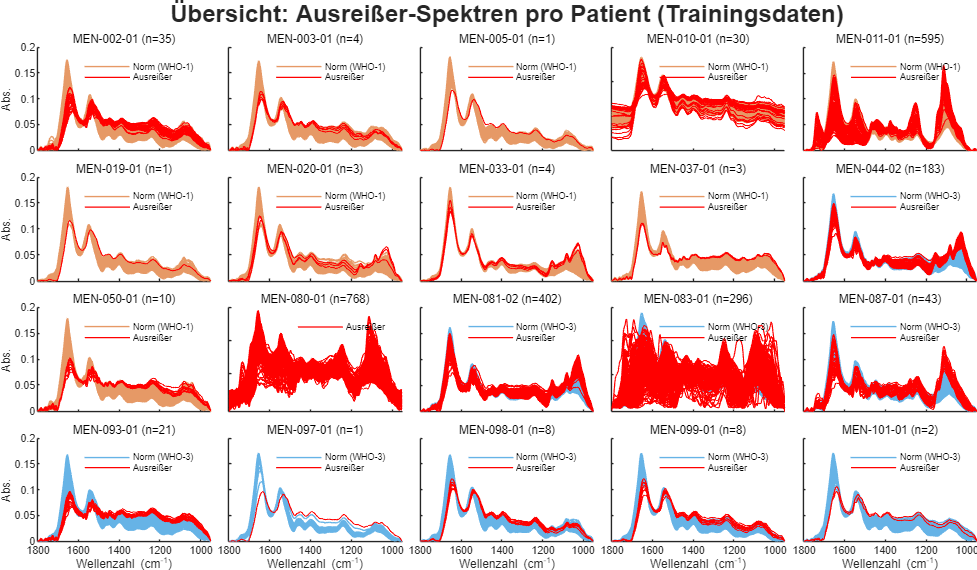

Kombinierte patientenweise Ausreißer-Abbildung gespeichert als: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_CombinedPatientOutlierPlots.tiff



% --- 2. Dimensionen für tiledlayout dynamisch bestimmen ---
% Ziel: ein einigermassen ausgewogenes Layout
if patient_plot_count == 1
    nrows_layout = 1;
    ncols_layout = 1;
else
    nrows_layout = floor(sqrt(patient_plot_count));
    if nrows_layout == 0, nrows_layout = 1; end % Falls patient_plot_count = 1 war (obwohl oben abgefangen)
    ncols_layout = ceil(patient_plot_count / nrows_layout);
end
% Wenn Sie wissen, dass es ca. 20 sind, könnten Sie auch festlegen, z.B.
% if patient_plot_count > 16 && patient_plot_count <= 20
%     nrows_layout = 4; ncols_layout = 5;
% elseif patient_plot_count > 12 && patient_plot_count <= 16
%     nrows_layout = 4; ncols_layout = 4;
% % etc. oder die dynamische Variante oben verwenden.
% end


% --- 3. Hauptabbildung und TiledLayout erstellen ---
% Die Figurengröße muss eventuell angepasst werden, je nach Anzahl der Subplots
fig_width = min(1920, ncols_layout * 350 + 100); % Etwas Platz für Ränder
fig_height = min(1080, nrows_layout * 300 + 100);

figCombined = figure('Name', 'Patienten-Ausreißer Übersicht', ...
                     'Position', [30, 30, fig_width, fig_height], ...
                     'PaperUnits', 'normalized', ...
                     'PaperPositionMode', 'auto');

tl = tiledlayout(nrows_layout, ncols_layout, 'TileSpacing', 'compact', 'Padding', 'tight');

% --- 4. Hauptüberschrift für die gesamte Abbildung ---
overall_main_title = 'Übersicht: Ausreißer-Spektren pro Patient (Trainingsdaten)';
title(tl, overall_main_title, 'FontSize', 16, 'FontWeight', 'bold');

% Linienstärken und Transparenz für Subplots
linewidth_non_outlier_patient = 0.6;
linewidth_outlier_patient = 0.8;
alpha_patient_non_outlier = 0.4;
subplot_fontsize = 8; % Kleinere Schriftgröße für Subplots

% --- 5. Durch Patienten mit Ausreißern iterieren und plotten ---
for i = 1:patient_plot_count
    current_patient_data = patients_with_outliers_info{i};
    current_patient_id = current_patient_data{1};
    num_outliers_for_patient = current_patient_data{2};
    patient_who_grade = current_patient_data{3};
    
    ax = nexttile; % Nächsten Subplot aktivieren
    hold(ax, 'on');
    
    % Daten für den aktuellen Patienten holen
    patient_global_indices = find(strcmp(Patient_ID_train, current_patient_id));
    patient_spectra_all = X_train(patient_global_indices, :);
    patient_outlier_status = outlier_indices_logical(patient_global_indices);
    
    patient_spectra_outliers = patient_spectra_all(patient_outlier_status, :);
    patient_spectra_non_outliers = patient_spectra_all(~patient_outlier_status, :);
    
    % Farbe für Nicht-Ausreißer
    if patient_who_grade == 'WHO-1'
        color_patient_non_outlier = colorWHO1;
    elseif patient_who_grade == 'WHO-3'
        color_patient_non_outlier = colorWHO3;
    else
        color_patient_non_outlier = [0.5 0.5 0.5]; % Grau als Fallback
    end
    
    % Plotten der Nicht-Ausreißer-Spektren
    legend_handles_non_outlier = [];
    if ~isempty(patient_spectra_non_outliers)
        for k = 1:size(patient_spectra_non_outliers, 1)
            plot(ax, wavenumbers_roi, patient_spectra_non_outliers(k,:), ...
                 'Color', [color_patient_non_outlier, alpha_patient_non_outlier], ...
                 'LineWidth', linewidth_non_outlier_patient, ...
                 'HandleVisibility', 'off');
        end
        if size(patient_spectra_non_outliers,1)>0
             h_non_outlier = plot(ax, wavenumbers_roi, patient_spectra_non_outliers(1,:), ... % Für Legende
                 'Color', [color_patient_non_outlier, alpha_patient_non_outlier], ...
                 'LineWidth', linewidth_non_outlier_patient, ...
                 'DisplayName', ['Norm (' char(patient_who_grade) ')']);
             legend_handles_non_outlier = h_non_outlier;
        end
    end
    
    % Plotten der Ausreißer-Spektren
    legend_handles_outlier = [];
    if ~isempty(patient_spectra_outliers)
        for k = 1:size(patient_spectra_outliers, 1)
            plot(ax, wavenumbers_roi, patient_spectra_outliers(k,:), ...
                 'Color', colorOutlier, ...
                 'LineWidth', linewidth_outlier_patient, ...
                 'HandleVisibility', 'off');
        end
         if size(patient_spectra_outliers,1)>0
            h_outlier = plot(ax, wavenumbers_roi, patient_spectra_outliers(1,:), ... % Für Legende
                 'Color', colorOutlier, ...
                 'LineWidth', linewidth_outlier_patient, ...
                 'DisplayName', 'Ausreißer');
            legend_handles_outlier = h_outlier;
         end
    end
    
    hold(ax, 'off');
    xlim(ax, [950 1800]); 
    ylim(ax, 'auto'); 
    % yticks(ax, 'auto'); % Kann bei vielen kleinen Plots überladen wirken
    set(ax, 'YTickLabel', []); % Y-Achsen-Ticks-Beschriftungen entfernen für mehr Platz
    set(ax, 'XTickLabel', []); % X-Achsen-Ticks-Beschriftungen für mittlere Plots entfernen
    if mod(i-1, ncols_layout) == 0 % Linke Spalte
         ylabel(ax, 'Abs.', 'FontSize', subplot_fontsize-1);
         set(ax, 'YTickLabelMode', 'auto'); % Nur für linke Spalte Y-Ticks zeigen
    end
    if i > patient_plot_count - ncols_layout % Letzte Zeile
        xlabel(ax, 'Wellenzahl (cm^{-1})', 'FontSize', subplot_fontsize-1);
        set(ax, 'XTickLabelMode', 'auto');  % Nur für unterste Reihe X-Ticks zeigen
        ax.XAxis.FontSize = subplot_fontsize-2;
    end
    
    title(ax, sprintf('%s (n=%d)', current_patient_id, num_outliers_for_patient), 'FontSize', subplot_fontsize, 'FontWeight', 'normal');
    set(ax, 'FontSize', subplot_fontsize-1);
    ax.XDir = 'reverse';
    
    % Legende nur wenn beide Typen von Handles existieren
    current_legend_handles = [legend_handles_non_outlier, legend_handles_outlier];
    current_legend_handles = current_legend_handles(~arrayfun(@(x) isempty(x) || ~isgraphics(x), current_legend_handles)); % Entferne leere Handles
    if ~isempty(current_legend_handles)
        legend(ax, current_legend_handles, 'Location', 'northeast', 'FontSize', subplot_fontsize-2, 'Box', 'off');
    end
    grid(ax, 'off'); % Kein Grid in Subplots
end

% --- 6. Speichern der kombinierten Abbildung ---
combinedFigName_tiff = strcat(datePrefix, '_CombinedPatientOutlierPlots.tiff');
combinedFigName_fig = strcat(datePrefix, '_CombinedPatientOutlierPlots.fig');

try
    exportgraphics(figCombined, fullfile(figuresDir, combinedFigName_tiff), 'Resolution', 300);
    savefig(figCombined, fullfile(figuresDir, combinedFigName_fig));
    disp(['Kombinierte patientenweise Ausreißer-Abbildung gespeichert als: ' fullfile(figuresDir, combinedFigName_tiff)]);
catch ME_export_combined
    warning('Konnte kombinierte Abbildung nicht speichern: %s', ME_export_combined.message);
end